w=[1000 1300 2100   2100, 2100;
   1000 1922 2457 , 1964 , 2700];
w=[1000, 1200, 1250, 1270, 1280, 1400, 1700, 2000 2100 2100, 2100 2100;
   1000, 1250, 1500, 1800, 1940, 2100, 2280, 2457 2200 1964  2600 2700];
sc=90/1024;
wx=(w-1000)*sc

wx =          0   17.5781   21.9727   23.7305   24.6094   35.1563   61.5234   87.8906   96.6797   96.6797   96.6797   96.6797
         0   21.9727   43.9453   70.3125   82.6172   96.6797  112.5000  128.0566  105.4688   84.7266  140.6250  149.4141


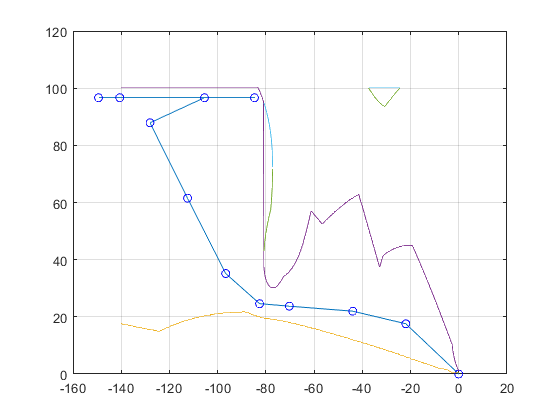

plot(-wx(2,:), wx(1,:))
hold on
grid on
plot(-wx(2,:), wx(1,:),'bo')

[Lis3 Dat]= runLenghtEncoding(flt1',0.2);

%[Lis10,Dat]= runLenghtEncoding(flt',1.0);
  for ni= 1:size(Dat,1)
    if Dat(ni,1)==-1
      Lis10(ni,:)= [0,Lis3(ni,1:end-1)];
    end
  end
Lis3(Lis3==0)=nan;
Lis10(Lis10==0)=nan;
RAD=pi/180;
scale=(max(theta1)-min(theta1))/size(flt1,1);
  plot((theta2/RAD)',Lis3*0.2)
% plot((theta2/RAD)',Lis10*2.5-9.5)
 hold off

Calculate neares neigbour

 p= 1500+ rand(2,1)*500

p = 	1.0e+03 *

    1.6327
    1.9623


 lMin=10000;
 id=0;
 for ni=1: length(w) 
 l= norm(p-w(:,ni))
 if l<lMin 
     lMin=l;
     id= ni;
 end
 
 end

l = 1.1516e+03

l = 833.3986

l = 600.1182

l = 397.3175

l = 353.3648

l = 270.3610

l = 324.7675

l = 616.1781

l = 524.3201

l = 467.3421

l = 790.6195

l = 873.2818

 sc=90/1024;
 wx=(w-1000)*sc

wx =          0   17.5781   21.9727   23.7305   24.6094   35.1563   61.5234   87.8906   96.6797   96.6797   96.6797   96.6797
         0   21.9727   43.9453   70.3125   82.6172   96.6797  112.5000  128.0566  105.4688   84.7266  140.6250  149.4141


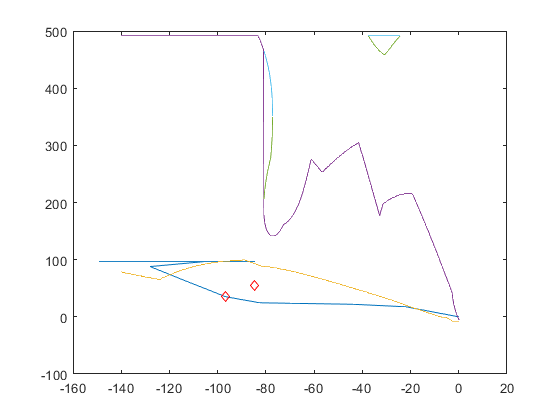

 plot(-wx(2,:), wx(1,:))
 hold on
 plot([-(p(2)-1000)*sc, -wx(2,id)],[(p(1)-1000)*sc, wx(1,id)],'rd');
 plot((theta2/RAD)',Lis3*1-9.5)
 hold off